# Demonstrates the dot product and cross product of vectors.

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗

syms a1 a2 a3 b1 b2 b3 real
a = [a1, a2, a3];
b = [b1, b2, b3];
d = dot(a,b)

$$d = a_{1}\,b_{1}+a_{2}\,b_{2}+a_{3}\,b_{3}$$

c = cross(a,b)

$$c = \left(\begin{array}{ccc} a_{2}\,b_{3}-a_{3}\,b_{2} & a_{3}\,b_{1}-a_{1}\,b_{3} & a_{1}\,b_{2}-a_{2}\,b_{1} \end{array}\right)$$

# Calculates an angle and the unit normal of a triangle defined by three points in the space.

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
p1 = [3, 5, 2];
p2 = [1, 0 ,0];
p3 = [3, -1, 0];
a = p2-p1;
b = p3-p1;
d = dot(a,b)

d =     34


theta = acosd(d/(norm(a)*norm(b)))

theta =        20.639


c = cross(a,b)

c =     -2    -4    12


theta = asind(norm(c)/(norm(a)*norm(b)))

theta =        20.639


n = c/norm(c)

n =      -0.15617     -0.31235      0.93704


# Derives the plane equation defined by three points in the space and plots the plane.

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
p1 = sym([3,5,2]);
p2 = sym([1,0,0]);
p3 = sym([3,-1,0]);
a = p2-p1;
b = p3-p1;
syms x y z
r = [x, y, z];
eq = dot(cross(a,b),r-p1)==0
fimplicit3(eq, [0 10])
axis vis3d

# Demonstrates the conversion of a symbolic expression to a numerical function.

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
z = solve(eq, z)

Error using  == 
Not enough input arguments.

z = matlabFunction(z)
[X,Y] = meshgrid(0:10,0:10);
Z = z(X,Y);
mesh(X,Y,Z)

# Demonstrates the solving of a system of n linear equations of n unknowns.

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
A = [1 2; 3 4]; b = [5; 6];
det(A)

ans =     -2


x = linsolve(A, b)

x =            -4
          4.5


x = A\b

x =            -4
          4.5


A = A'; b = b';
det(A)

ans =     -2


x = b/A

x =            -4          4.5


A = [1 2; 3 6]; b = [5; 6];
det(A)

ans =   -3.3307e-16


x = A\b

x =   -5.4043e+16
   2.7022e+16


b = [5; 15];
x = A\b

x =             0
          2.5


# Solves the system of linear equations governing the 3-bar truss problem in Section 3.14.

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
a = sqrt(2)/2;
A = [-a  a  0  0  0  0;
     -a -a  0  0  0  0;
      a  0  1  1  0  0;
      a  0  0  0  1  0;
      0 -a -1  0  0  0;
      0  a  0  0  0  1];
b = [0, 1000, 0, 0, 0, 0]';
x = A\b
x = linsolve(A,b)

x =       -707.11
      -707.11
          500
            0
          500
          500


det(A)

ans =            -1


A = A';
b = b';
x = b/A

x =       -707.11      -707.11          500            0          500          500


# Solves a system of linear equations by means of the LU factorization.

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
a = sqrt(2)/2;
A = [-a  a  0  0  0  0;
     -a -a  0  0  0  0;
      a  0  1  1  0  0;
      a  0  0  0  1  0;
      0 -a -1  0  0  0;
      0  a  0  0  0  1];
b = [0, 1000, 0, 0, 0, 0]';
[L,U] = lu(A)

L =             1            0            0            0            0            0
            1            1            0            0            0            0
           -1         -0.5            1            0            0            0
           -1         -0.5            0            0            1            0
            0          0.5           -1            1            0            0
            0         -0.5            0            0            0            1


U =      -0.70711      0.70711            0            0            0            0
            0      -1.4142            0            0            0            0
            0            0            1            1            0            0
            0            0            0            1            0            0
            0            0            0            0            1            0
            0            0            0            0            0            1


y = L\b

y =            0
        1000
         500
           0
         500
         500


x = U\y

x =       -707.11
      -707.11
          500
            0
          500
          500


# Demonstrates the solving of an eigenvalue problem, Kx = λMx.

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
K = [40, -25,   0;
    -25,  50, -30;
      0, -30,  60]

K =     40   -25     0
   -25    50   -30
     0   -30    60


M = diag([3, 4, 5])

M =      3     0     0
     0     4     0
     0     0     5


[X, Lamda] = eig(K, M)

X =       -0.2788      0.39184     -0.31947
     -0.35468      0.03366      0.35081
     -0.22961     -0.32706     -0.20077


Lamda =        2.7318            0            0
            0       12.617            0
            0            0       22.484


Omega = sqrt(Lamda)

Omega =        1.6528            0            0
            0       3.5521            0
            0            0       4.7417


# Demonstrates the manipulations of polynomials

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
p = [1, -2, -1, 2];
polyval(p, 3)
x = linspace(-2,3);
plot(x, polyval(p,x)), grid on
r = roots(p)
poly(r)
p1 = polyint(p)
polyder(p1)
a = [1, 3, 5];
b = [2, 4, 6];
c = polyder(a,b)
[n,d] = polyder(a,b)

# Does the same tasks as Example10_05a, using symbolic mathematics.

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
syms x
p(x) = poly2sym([1, -2, -1, 2])
p(3)
fplot(p), axis([-2,3,-12,8]), grid on
r = solve(p)
p1 = int(p)
diff(p1)
a = poly2sym([1, 3, 5])
b = poly2sym([2, 4, 6])
c = diff(a*b)
[n,d] = numden(diff(a/b))

# Finds the polynomials of degrees 1, 2, and 3 that best fit a set of 2-D data points.

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
T = [ 33, 144, 255, 366, 477, 589, 700, 811, 922];
E = [220, 213, 206, 199, 192, 185, 167, 141, 105];
temp = 0:50:1000;
format shortG
for k = 1:3
    P = polyfit(T, E, k)
    young = polyval(P, temp);
    subplot(2,2,k)
    plot(T, E, 'o', temp, young)
    axis([0,1000,100,250])
    xlabel('Temperature (K)')
    ylabel('Young''s Modulus (GPa)')
    title(['Polynomial of Degree ', num2str(k)])
    residual = E - polyval(P, T);
    error = norm(residual)
    R = sqrt(1-error^2/norm(E)^2)
end

P =      -0.11514       235.86


error =        37.055


R =       0.99775


P =   -0.00015541     0.033291       213.23


error =        15.469


R =       0.99961


P =   -2.9124e-07   0.00026175     -0.12346       224.67


error =        3.3894


R =       0.99998


# Uses an interactive curve-fitting tool to perform the tasks in Example10_06

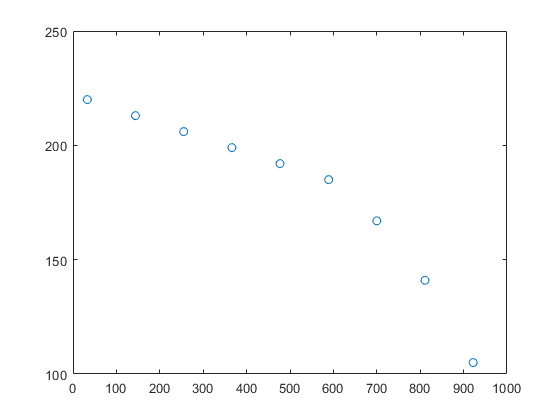

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
T = [ 33, 144, 255, 366, 477, 589, 700, 811, 922];
E = [220, 213, 206, 199, 192, 185, 167, 141, 105];
plot(T, E, 'o')
axis([0, 1000, 100, 250])

# Finds a line through origin that best-fits the data points.

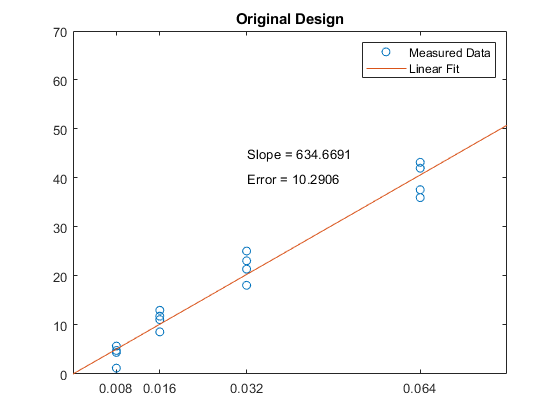

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
x = [0.008, 0.008, 0.008, 0.008, ...
     0.016, 0.016, 0.016, 0.016, ...
     0.032, 0.032, 0.032, 0.032, ...
     0.064, 0.064, 0.064, 0.064];
y = [4.8,  1.2,  5.7,  4.4, ...
    11.1,  8.6, 13.0, 11.8, ...
    23.1, 18.1, 25.1, 21.4, ...
    42.0, 36.0, 43.2, 37.6];
slope = sum(x.*y)/sum(x.^2);
residual = y-slope*x;
error = norm(residual);
plot(x,y,'o'), hold on
hAxes = gca;
hAxes.XTick = [0.008,0.016,0.032,0.064];
axis([0,0.08,0,70]);
plot([0,0.08],[0,slope*0.08])
text(0.032, 45, ['Slope = ', num2str(slope)])
text(0.032, 40, ['Error = ', num2str(error)])
legend('Measured Data', 'Linear Fit')
title('Original Design')

# Finds a line through origin that best-fits the data points representing an improved design.

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
x = [0.008, 0.008, 0.008, 0.008, ...
     0.016, 0.016, 0.016, 0.016, ...
     0.032, 0.032, 0.032, 0.032, ...
     0.064, 0.064, 0.064, 0.064];
y = [5.3,  4.6,  5.8,  5.4, ...
    12.2, 10.1, 13.2, 11.9, ...
    24.6, 23.1, 25.0, 24.3, ...
    49.3, 47.1, 50.1, 48.2];
slope = sum(x.*y)/sum(x.^2);
residual = y-slope*x;
error = norm(residual);
plot(x,y,'o'), hold on
hAxes = gca;
hAxes.XTick = [0.008,0.016,0.032,0.064];
axis([0,0.08,0,70]);
plot([0,0.08],[0,slope*0.08])
text(0.032, 45, ['Slope = ', num2str(slope)])
text(0.032, 40, ['Error = ', num2str(error)])
legend('Measured Data', 'Linear Fit')
title('Improved Design')

# Finds a line through origin that best-fits the data points representing an improved design.

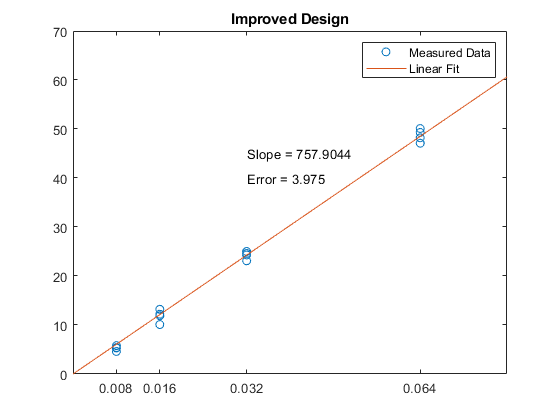

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
x = [0.008, 0.008, 0.008, 0.008, ...
     0.016, 0.016, 0.016, 0.016, ...
     0.032, 0.032, 0.032, 0.032, ...
     0.064, 0.064, 0.064, 0.064];
y = [5.3,  4.6,  5.8,  5.4, ...
    12.2, 10.1, 13.2, 11.9, ...
    24.6, 23.1, 25.0, 24.3, ...
    49.3, 47.1, 50.1, 48.2];
slope = sum(x.*y)/sum(x.^2);
residual = y-slope*x;
error = norm(residual);
plot(x,y,'o'), hold on
hAxes = gca;
hAxes.XTick = [0.008,0.016,0.032,0.064];
axis([0,0.08,0,70]);
plot([0,0.08],[0,slope*0.08])
text(0.032, 45, ['Slope = ', num2str(slope)])
text(0.032, 40, ['Error = ', num2str(error)])
legend('Measured Data', 'Linear Fit')
title('Improved Design')

# Finds a line through origin that best-fits the data points representing an improved design.

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
x = [0.008, 0.008, 0.008, 0.008, ...
     0.016, 0.016, 0.016, 0.016, ...
     0.032, 0.032, 0.032, 0.032, ...
     0.064, 0.064, 0.064, 0.064];
y = [5.3,  4.6,  5.8,  5.4, ...
    12.2, 10.1, 13.2, 11.9, ...
    24.6, 23.1, 25.0, 24.3, ...
    49.3, 47.1, 50.1, 48.2];
slope = sum(x.*y)/sum(x.^2);
residual = y-slope*x;
error = norm(residual);
plot(x,y,'o'), hold on
hAxes = gca;
hAxes.XTick = [0.008,0.016,0.032,0.064];
axis([0,0.08,0,70]);
plot([0,0.08],[0,slope*0.08])
text(0.032, 45, ['Slope = ', num2str(slope)])
text(0.032, 40, ['Error = ', num2str(error)])
legend('Measured Data', 'Linear Fit')
title('Improved Design')

# Performs linear/spline interpolations.

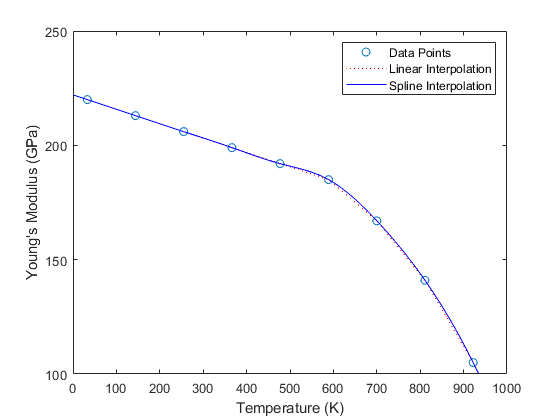

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
T = [ 33, 144, 255, 366, 477, 589, 700, 811, 922];
E = [220, 213, 206, 199, 192, 185, 167, 141, 105];
plot(T, E, 'o'), hold on
temp = 0:10:1000;
young = interp1(T, E, temp);
plot(temp, young, 'r:')
young = interp1(T, E, temp, 'spline');
plot(temp, young, 'b-')
axis([0,1000,100,250])
xlabel('Temperature (K)')
ylabel('Young''s Modulus (GPa)')
legend('Data Points', 'Linear Interpolation', 'Spline Interpolation')

# Demonstrates how to find a root of an algebraic equation.

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
x = linspace(0,pi);
y = sin(x)+2*cos(x)-0.5;
plot(x,y,[0,pi], [0,0]), hold on
axis([0, pi, -2.5, 2])
x1 = interp1(y,x,0)
plot([x1, x1], [-2.5, 2])
text(x1,0.1,num2str(x1))

# Demonstrates 2-D interpolation.

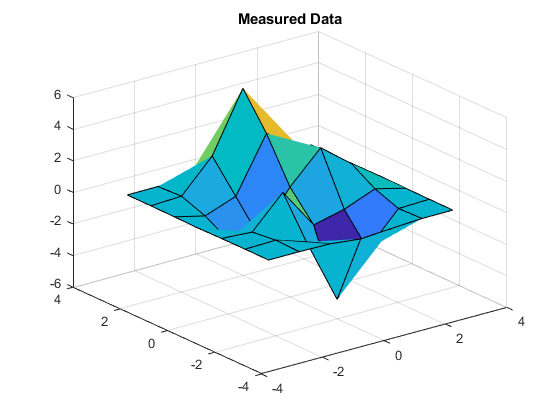

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
[X,Y] = meshgrid(-3:3);
Z = peaks(X,Y);
surf(X,Y,Z)
title('Measured Data')

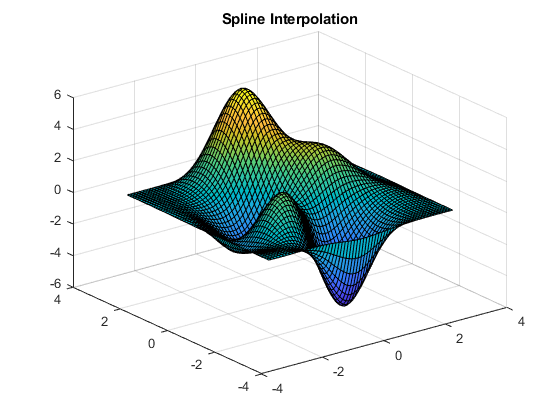

[X1,Y1] = meshgrid(-3:0.1:3);
Z1 = interp2(X,Y,Z,X1,Y1,'spline');
figure
surf(X1,Y1,Z1)
title('Spline Interpolation')